# Design and Comparison of FIR and IIR Filters (200 Points)

Welcome to Lab 3!

In this lab, you will design and compare FIR and IIR filters. Refer to the below diagram for the lab.  

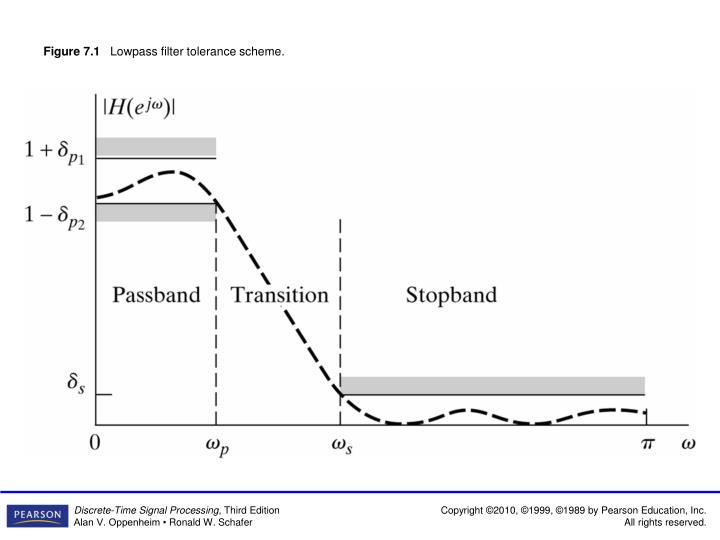

## FIR Filter Design (40 Points)

Now, we will design FIR filters satisfying the following specifications: 

- 
$$\omega_p =0.4\pi
$$


- 
$$\omega_s = 0.6\pi
$$
 

- 
$$\delta_{p_1}=\delta_{p_2}=0.01, \;\;\delta_s=0.01$$


### Windowing Method (20 Points)

Now, using the Kaiser window, come up with a window-based FIR filter with the above specifications (presented just after the first image of the notebook)

For theoretical understanding, see (i) page 499, Example 7.8 of the Second Edition of the textbook, or (ii) page 569, Section 6.1 of Third Edition of your textbook.  

- From your theoretical understanding, what is the filter order (approx)?  $\textrm{filter}\;\textrm{order}=\frac{-20\log \left(\delta_{P_1 } +\delta_{p_2 } \right)-7\ldotp 95}{2\ldotp 285\left(F_s -F_p \right)}\approx 23$

- Open "filterDesigner" tool (you can open it by typing *filterDesigner* in the Matlab command window as shown below.)

                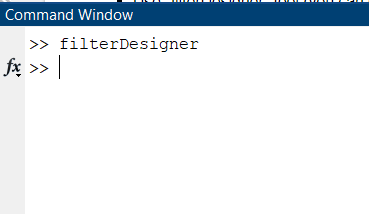

       Open the below view. Here you can specify frequency and magnitude specifications. 

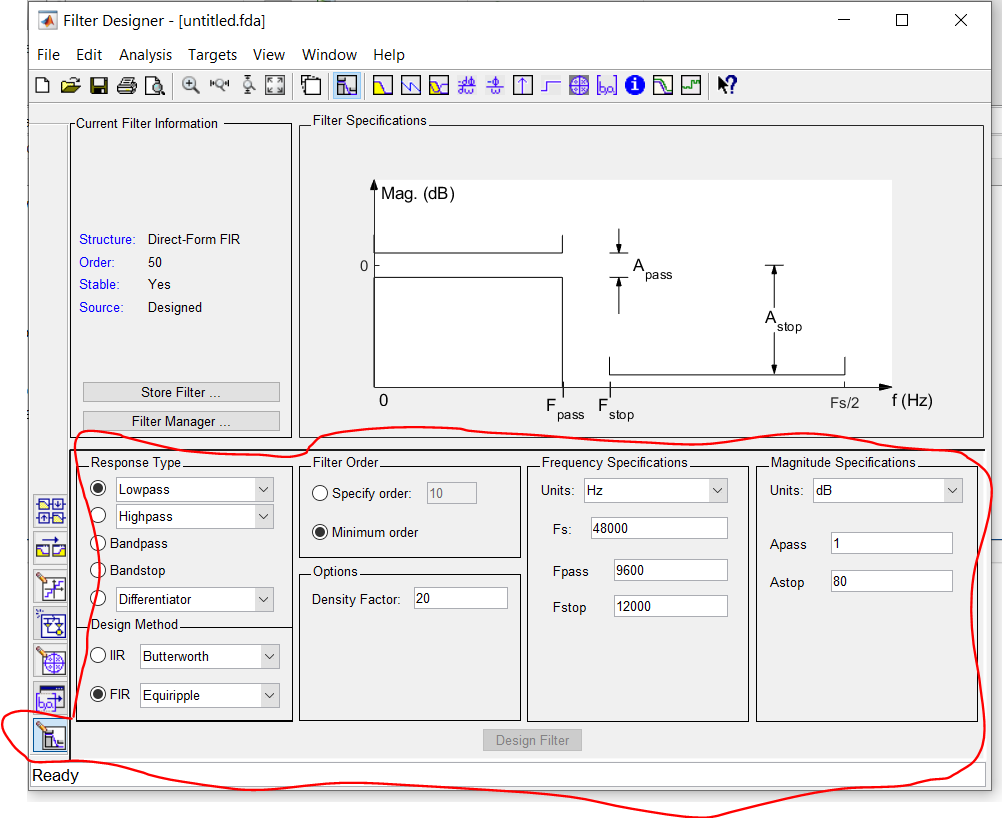

-   Obtain the coefficients of the filter. Write down the coefficients below. 

% ASSIGN THE FILTER COEFFICIENTS TO "b". 
%used the filterDesigner tool and exported the coefficients to the workspace

b = [-0.00290721195538428	-0.00490366535065810	0.00755683586712887	0.0110226954797965	-0.0155225401770831	-0.0213991976073607	0.0292358909969873	0.0401345917148615	-0.0564719201141760	-0.0844683882321540	0.147031071648378	0.450691837729664	0.450691837729664	0.147031071648378	-0.0844683882321540	-0.0564719201141760	0.0401345917148615	0.0292358909969873	-0.0213991976073607	-0.0155225401770831	0.0110226954797965	0.00755683586712887	-0.00490366535065810	-0.00290721195538428];

disp(b);

  Columns 1 through 12

   -0.0029   -0.0049    0.0076    0.0110   -0.0155   -0.0214    0.0292    0.0401   -0.0565   -0.0845    0.1470    0.4507

  Columns 13 through 24

    0.4507    0.1470   -0.0845   -0.0565    0.0401    0.0292   -0.0214   -0.0155    0.0110    0.0076   -0.0049   -0.0029



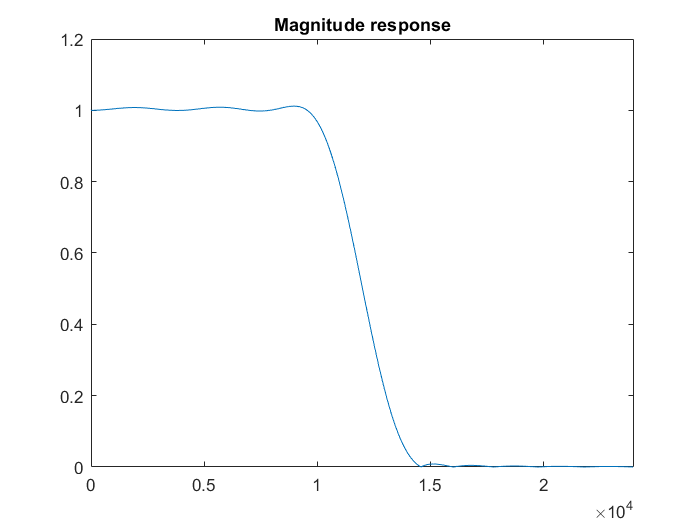

Fs = 48000;
N = 1024;
f = (-N/2 : 1 : N/2 -1)*Fs/N;
plot(f , abs(fftshift(fft(b,N))));
xlim([0 Fs/2]);
title("Magnitude response");

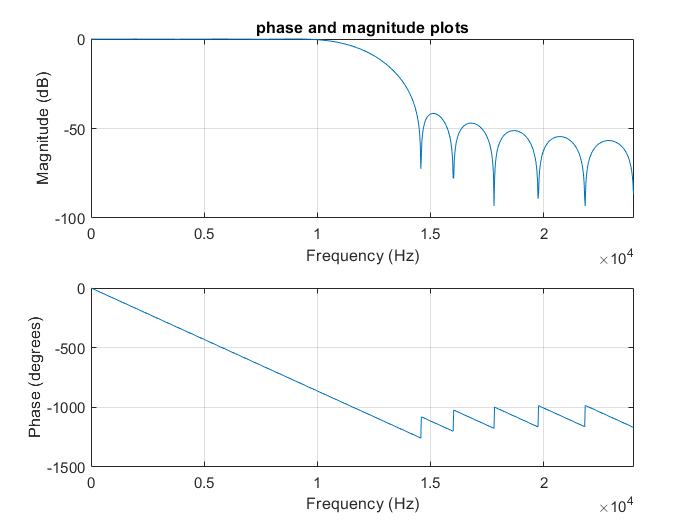

freqz(b,1,N,Fs)
title("phase and magnitude plots")

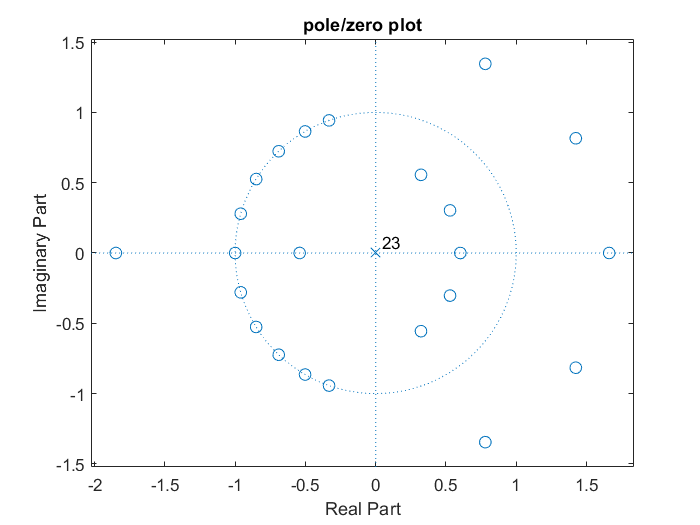

zplane(b)
title("pole/zero plot")

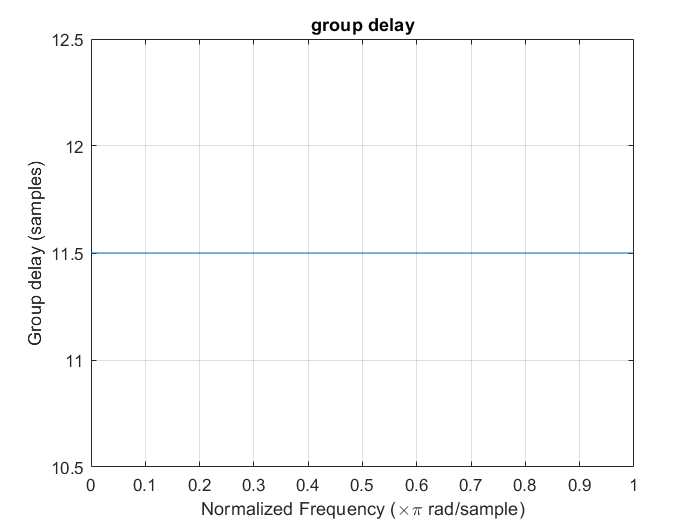

grpdelay(b)
title("group delay")

- Does the number of entries in $b$ correspond to the above theoretically obtained filter order?

           * Yes, the entries in b are related to the order of the filter, if the order is n then we will get n+1 coefficients.*

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.  

            ***Observations:***

            *Magnitude response**: By looking at the magnitude response in DB we can observe an Equiripple behaviour for the stop band but not for passband (log tends to zero in passband).*

*By looking at the magnitude response (linear) we observed Equiripple behaviour for the passband  but not the stopband.(linear scale tends to zero in stopband).*

           *Poles and Zeros**: By looking at the pole zeros plot we can conclude that the filter is stable as all the 23  poles lie on the origin (i.e. inside the unit circle).*

           *Group Delay:** Group delay is constant for the above filter as the filter is of FIR type and hence has a generalized linear phase.*

           *Phase response**: phase response is constantly decreasing in the passband and transition band but shows some irregularities in the stop band.*

### Min-Max Method (20 Points): 

You already know that the the FIR filter designed using the windowing method has minimimum mean squared error with respect to the ideal filter response. Now, we will design a filter which minimizes the maximum error with respect to the ideal filter. Now watch "Week-6 Video-3.mp4" to understand the theory behind the optimal min-max FIR filter design method. Design an FIR filter satisfying the  specifications presented just after the first image of the notebook using  [firpm](https://in.mathworks.com/help/signal/ref/firpm.html).

% WRITE YOUR CODE HERE
% finding order
[n,fo,ao,w] = firpmord([9600 14400],[1 0],[0.01 0.01],48000);

%defining the filter
b1 = firpm(n,fo,ao);
disp(b1);

  Columns 1 through 12

    0.0060    0.0121   -0.0155   -0.0191    0.0279    0.0385   -0.0557   -0.0829    0.1464    0.4483    0.4483    0.1464

  Columns 13 through 20

   -0.0829   -0.0557    0.0385    0.0279   -0.0191   -0.0155    0.0121    0.0060



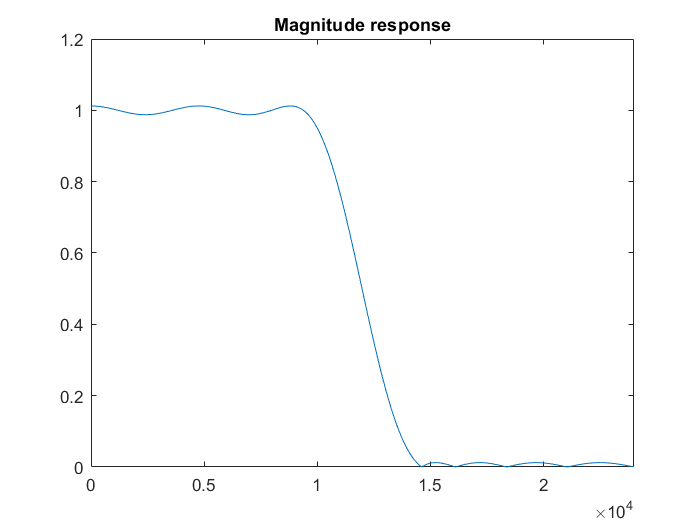

plot(f,abs(fftshift(fft(b1,N))));
xlim([0 Fs/2]);
title("Magnitude response");

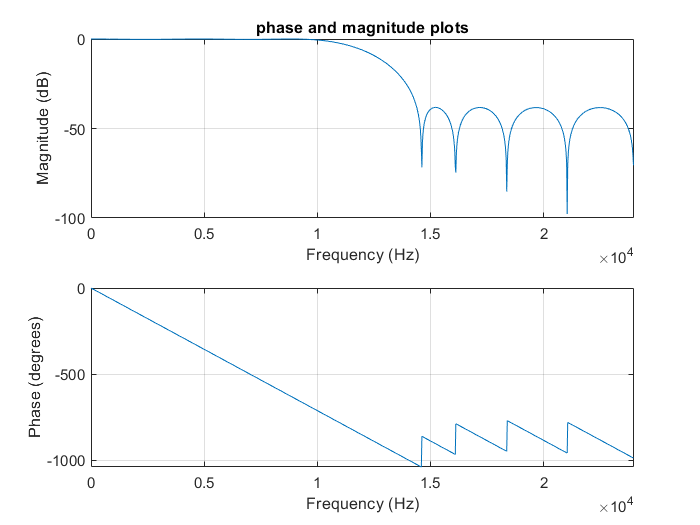

freqz(b1,1,1024,Fs)
title("phase and magnitude plots")

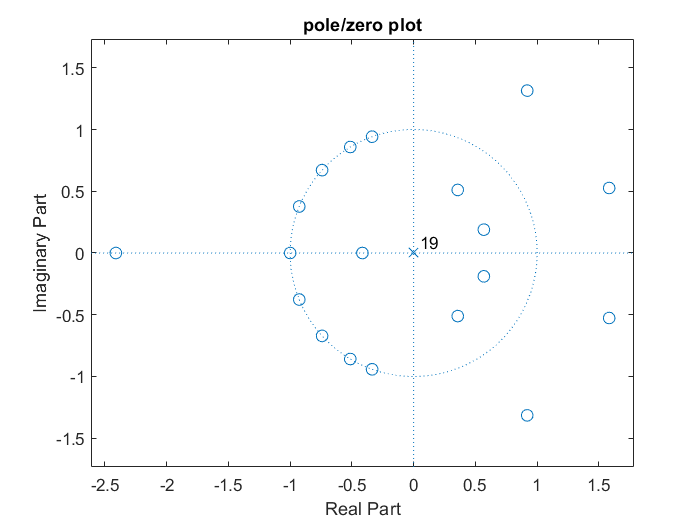

zplane(b1)
title("pole/zero plot")

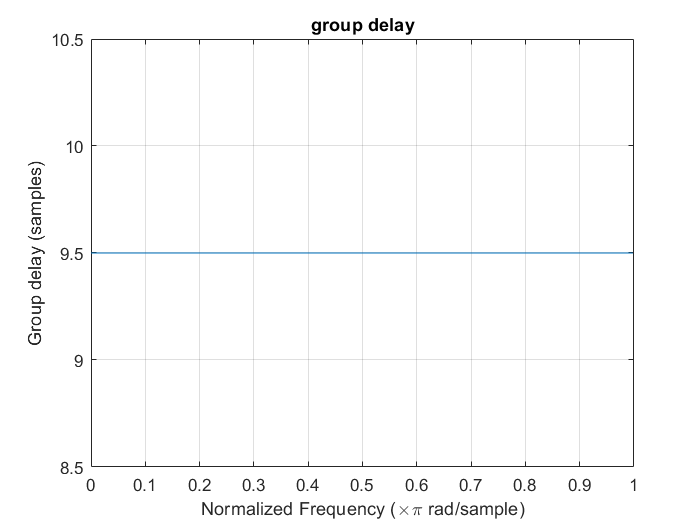

grpdelay(b1);
title("group delay");

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.      

            ***ANSWER:  ***

- *We see 19 zeros (at origin) in the pole zero plot. *

- *All poles are inside the unit circle, so the filter is stable.*

- *The magnitude response for Fs = 48000 Hz is 0 dB in the passband till Fpass = 9600 Hz. We see a transition from Fpass to Fstop = 14400 Hz. The magnitude of side lobes in the stopband remain below -40 dB.*

- *The phase decreases linearly in the passband as well as the transition region which indicates that its a linear phase filter but some irregularities near the side lobes.*

- *The group delay response is a constant value of 11.5 (as it a FIR filter).*

- Give a comparison with the filter obtained using the windowing method above.  

            ***ANSWER****:*

- *The min max type of FIR filter has a lower order and hence is computationally less expensive.*

- *As the orders are different the group delays for both have different constant value.*

- *The side lobe amplitude is decreasing for higher frequencies in the filter obtained by windowing whereas the amplitudes of the side lobes is constant for filter designed with min max method.*

## IIR Filter Design (100 Points)

In this part, we will solve Example 5 of Chapter 7 of Oppenheim and Schafer textbook using the *filterDesigner* tool. Although you need to know how impulse invariance and bilinear transform methods work, you almost never design discrete-time filters manually. Almost always, you will use some tools, such as *filterDesigner* MATLAB. 

**Note:**  From this course point of view, you should know how to manually design filters using impulse invariance and bilinear transform for IIR filters, and window and equiripple (also called as minimax or Parks-McClellan methods) for FIR filters. 

**References:** 

- Example 5 of Chapter 7 of Oppenheim and Shafer textbook, 3rd Edition (If you have the 2nd Edition, see Example 7.4, 7.5 and 7.6 for the IIR part starting from Page 458, and Section 7.5.1 on Page 503 for FIR part )

- [https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf](https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf)

- Relevant Week7 videos from EE321 Course. Watch "Week-7 Video-2.mp4" for the Bilinear Transform method for IIR Filter design method (note that we had skipped this in the theory part of the course)

Design the following filter: $\delta_{p_1} = \delta_{p_2} = 0.01, \;\;
\delta_s = 0.001, \;\; \omega_p = 0.4\pi, \;\; \omega_s = 0.6\pi
$using

- IIR Butterworth

- IIR Chebyshev Type 1

- IIR Chebyshev Type 2

- IIR Elliptic

- FIR Window - Kaiser

- FIR Equiripple 

and answer the following for each of the above methods: 

- Order of the filter

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

An example is shown below for IIR Butterworth filter: 

### IIR Butterworth filter

Open the Filter Designer tool, by typing *filterDesigner *in the command window as shown below. 

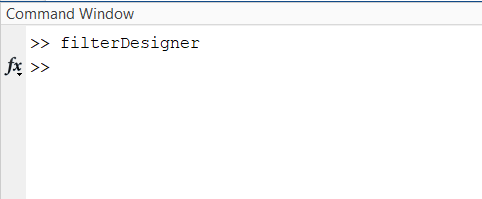

We first note that in the Filter Designer tool, for designing IIR filter,  it is assumed that $\delta_{p_1}=0
$ (red annotations in Fig. 1). Hence, in order to design the filter using this tool,  we first scale all the tolerance parameters, design the filter using the toolbox and then rescale them back.

- **Scaling the parameters:** Let $\delta_{p_1}',\; \delta_{p_2}'$and $\delta_s'$ be the new parameters.  We want to scale all the parameters according to the requirement that $\delta_{p_1}'=0$.  This implies, $1-\delta_{p_2}' = (1-\delta_{p_2})/(1+\delta_{p_1}) = (1-0.01)/1.01=  0.9802$. Hence, $\delta_{p_2}' = 1-0.9802=0.0198$. Similarly, $\delta_s' = \delta_s/(1+\delta_{p_1}) = 0.001/1.01 = 0.00099$. 

- **Filter Design:** Now, we feed these values in the Filter Designer tool  and design the filter (blue annotations in Fig. 1)

. 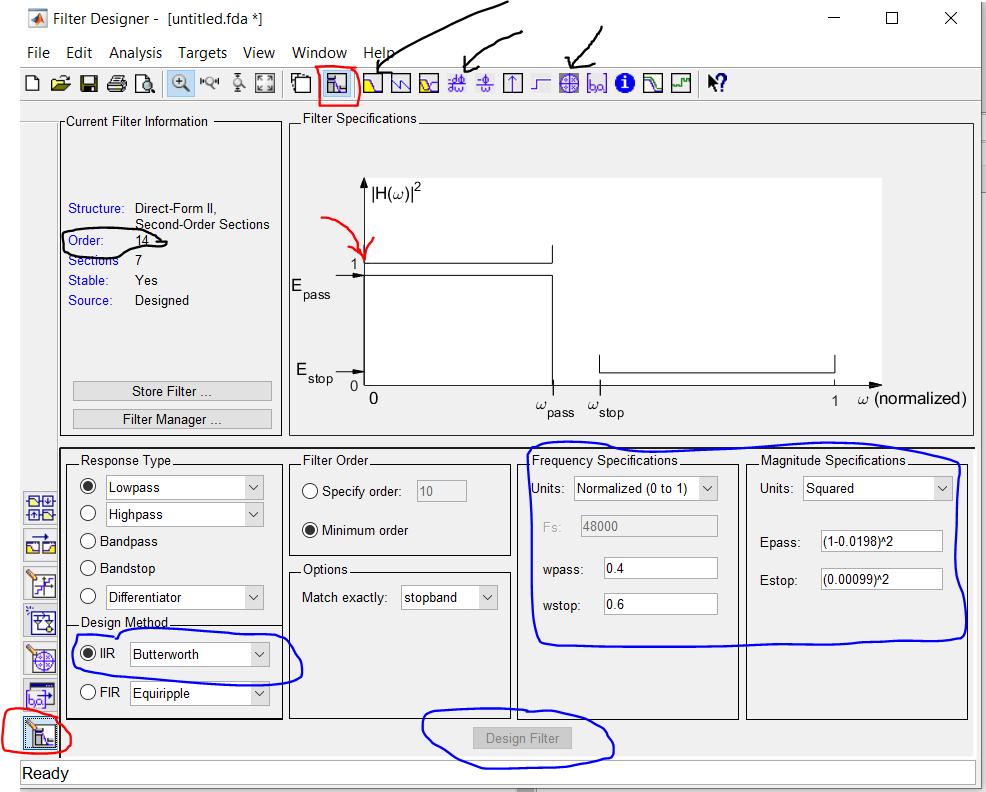

                                                      Fig 1: IIR Butterworth Filter Design

- **Rescaling parameters:**  Now, if you look at the magnitude response (by clicking on the tab besides the red annotated box), you can see that the above filter has gain of $0.9914$at $0.4\pi
$and $0.00099$at $0.6\pi$. Note that the design already satisfies the required specification. However, in some cases, if the required specification is not met, you need to rescale back the impulse response or numerator coefficients by $1+{\delta_{p_1}}$ to match the desired response. 

- **Filter Analysis: **Now, we will look at magnitude response, group delay and pole-zero plots and order of the filter (black annotations in Fig. 1). 

              - Filter order is 14. 

              - Both passband and stopbands have monotonic behaviour. 

              - There are 14 zeros at $-1$. Since all the poles are  inside the unit circle, the filter is stable. 

              - The group delay is highest in the transition band and below 15 in the passband. 

          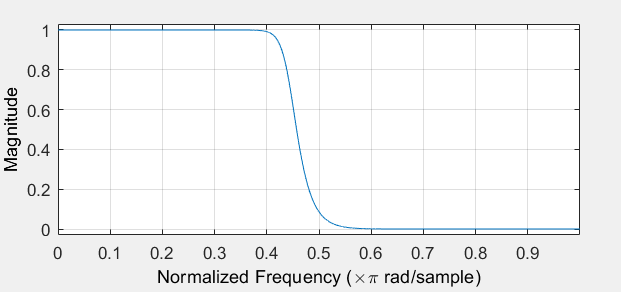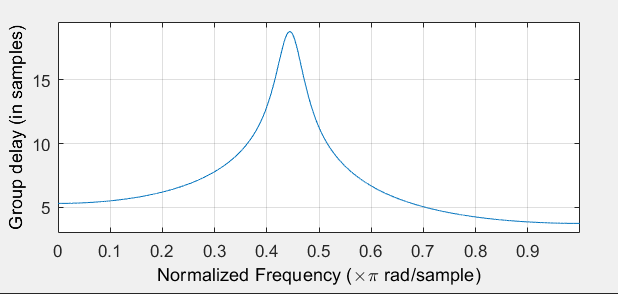

                               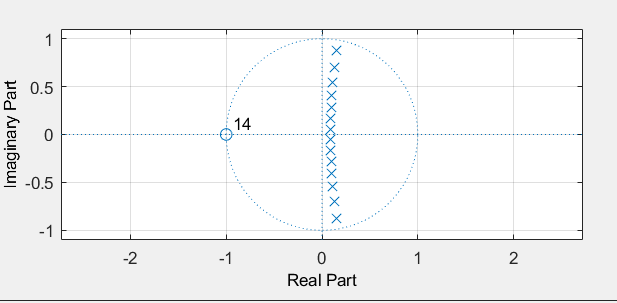

### IIR Chebyshev Type 1 (10 Points)

% Enter the filter coefficients
%used the filterDesigner tool and exported the coefficients to the workspace

cheby1Filter = [ [1	2	1	1	-0.546973251226029	0.898834056379833];[1	2	1	1	-0.717257651116436	0.713657895463924];[1	2	1	1	-1.01523783975706	0.548112152489310];[1	2	1	1	-1.26265789161358	0.438338863184365]];
G_cheby1 = [0.337965201288451 0.249100061086872 0.133218578183062 0.0439202428926966 0.980200000000000];

for i = 1:4
   disp("Section " + i);
   disp("    Numerator");
   disp(cheby1Filter(i,1:3));
   disp("    Denominator");
   disp(cheby1Filter(i,4:6));
end

Section 1


    Numerator


     1     2     1



    Denominator


    1.0000   -0.5470    0.8988



Section 2


    Numerator


     1     2     1



    Denominator


    1.0000   -0.7173    0.7137



Section 3


    Numerator


     1     2     1



    Denominator


    1.0000   -1.0152    0.5481



Section 4


    Numerator


     1     2     1



    Denominator


    1.0000   -1.2627    0.4383



Answer the following:

- Order of the filter

*              Order of the fillter is 8.*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            The Passband shows equiripple behaviour whereas the stopband shows monotonic behaviour.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

            **Magnitude:-**

            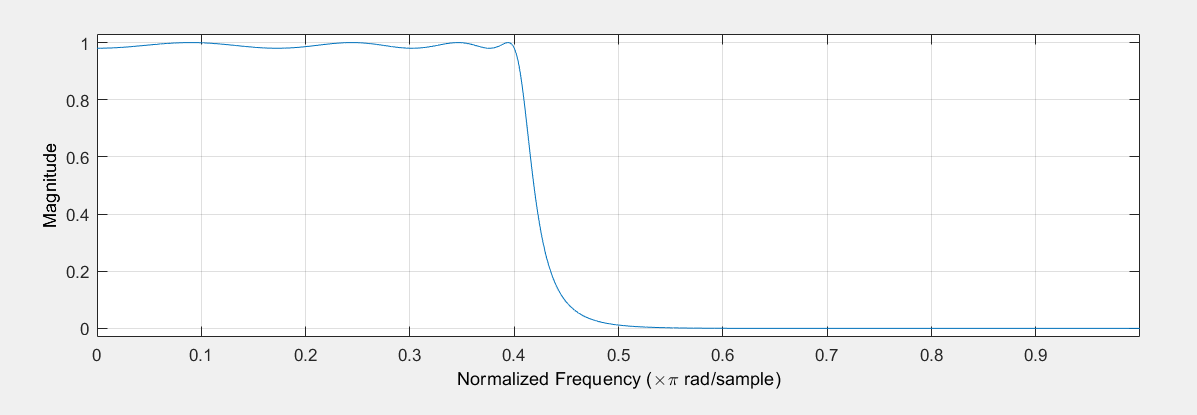

**            Magnitude in DB:-**

            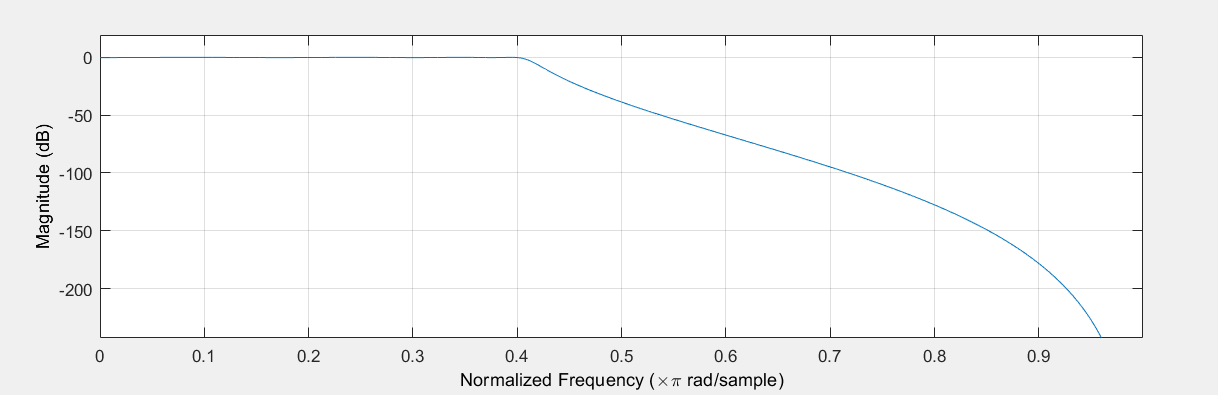 

           **Group Delay:-**

           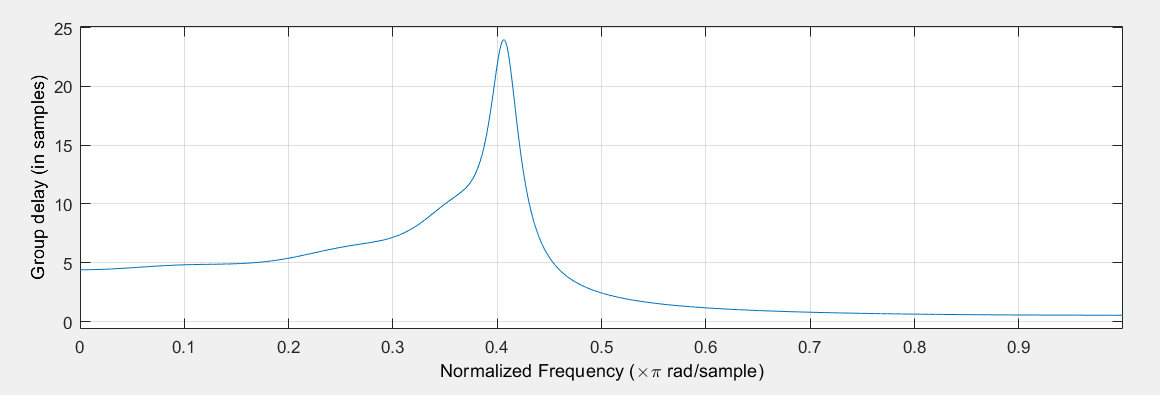

         **Pole Zero:-**

###         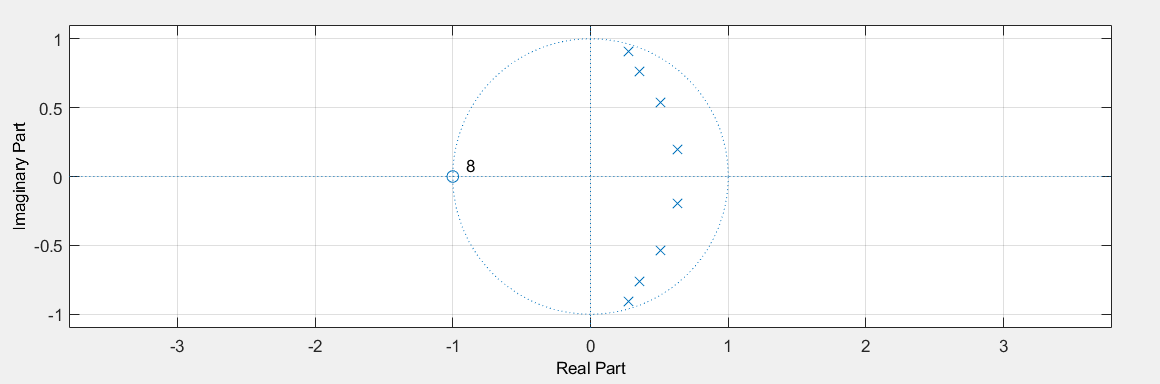

         **Observations:**

- The filter is stable as all the poles of the pole zero plot lie inside the unit circle.

- The group delay is highest in the transition band and below 25 in the passband. 

- Passband shows equiripple behaviour and stopband shows monotonic behaviour.

### IIR Chebyshev Type 2 (10 Points)

% Enter the filter coefficients
%used the filterDesigner tool and exported the coefficients to the workspace

cheby2Filter = [ [1	0.652918507109619	1	1	-0.255851164429155	0.735710837279689];[1	0.930543693580330	1	1	-0.126044716922436	0.368240180009988];[1	1.43958909021804	1	1	-0.000530079383103342	0.135851582247154];[1	1.92122021958431	1	1	0.0776761022060578	0.0170844887453150]];
G_cheby2 = [0.557823268556732 0.423878840574435 0.330074748199669 0.279188754940019 1];

for i = 1:4
   disp("Section " + i);
   disp("    Numerator");
   disp(cheby2Filter(i,1:3));
   disp("    Denominator");
   disp(cheby2Filter(i,4:6));
end

Section 1


    Numerator


    1.0000    0.6529    1.0000



    Denominator


    1.0000   -0.2559    0.7357



Section 2


    Numerator


    1.0000    0.9305    1.0000



    Denominator


    1.0000   -0.1260    0.3682



Section 3


    Numerator


    1.0000    1.4396    1.0000



    Denominator


    1.0000   -0.0005    0.1359



Section 4


    Numerator


    1.0000    1.9212    1.0000



    Denominator


    1.0000    0.0777    0.0171



Answer the following:

- Order of the filter

*            Order of the filter is 8.*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            The Passband shows monotonic behaviour whereas the stopband shows equiripple behaviour. *

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

          **Magnitude:-**

          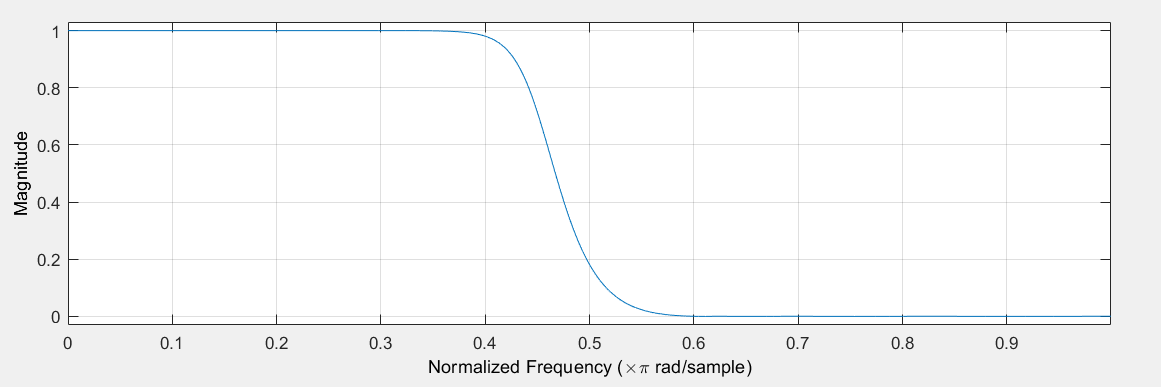

         **Magnitude in DB:-**

         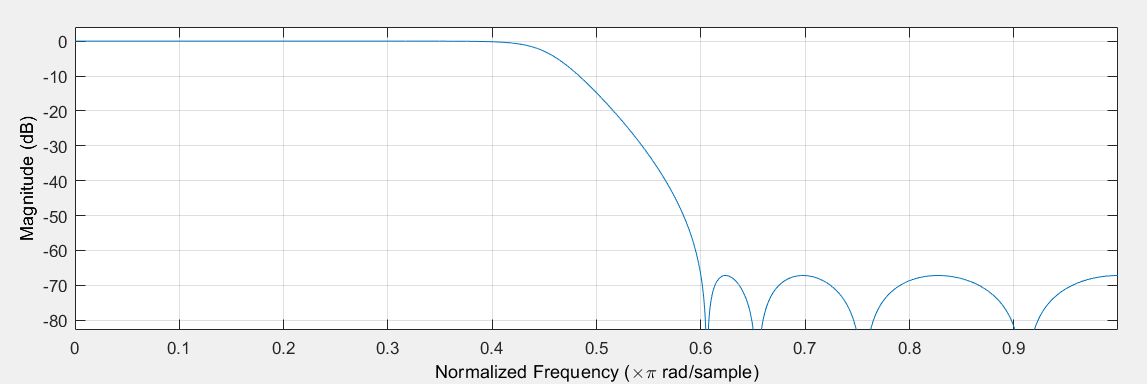                

        ***Group Delay*****:-**

        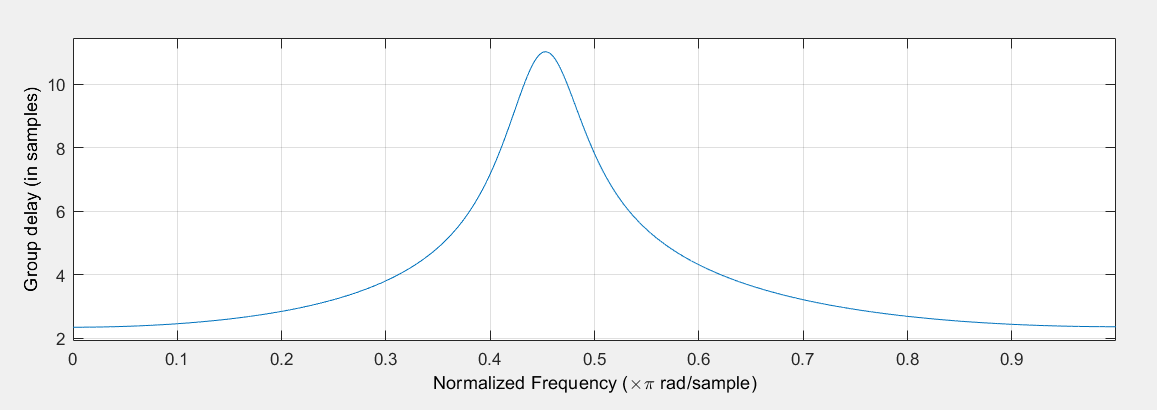

       **Pole Zero:-**

       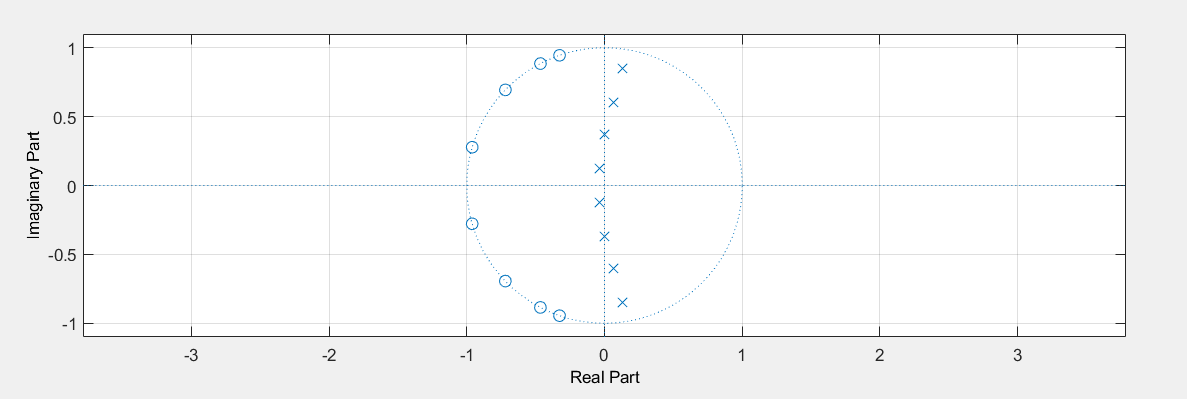

       **Observations:**

- The filter is stable as all the poles of the pole zero plot lie inside the unit circle.

- The group delay is highest in the transition band and below 10 in the passband. 

- Passband shows monotonic behaviour and stopband shows equiripple behaviour.

### IIR Elliptic (10 Points)

% Enter the filter coefficients
%used the filterDesigner tool and exported the coefficients to the workspace

ellipticFilter = [ [1	0.694834977219487	1	1	-0.689759787076362	0.589278853747360]; [1	1.72549033422845	1	1	-0.942628228849249	0.297853307679337]; [1	0.219329979159607	1	1	-0.522872296977416	0.873850552922561] ]

ellipticFilter =     1.0000    0.6948    1.0000    1.0000   -0.6898    0.5893
    1.0000    1.7255    1.0000    1.0000   -0.9426    0.2979
    1.0000    0.2193    1.0000    1.0000   -0.5229    0.8739


G_elliptic = [0.774092875298320 1.56018344006996 0.0157242818381364 1];

for i = 1:3
   disp("Section " + i);
   disp("    Numerator");
   disp(ellipticFilter(i,1:3));
   disp("    Denominator");
   disp(ellipticFilter(i,4:6));
end

Section 1


    Numerator


    1.0000    0.6948    1.0000



    Denominator


    1.0000   -0.6898    0.5893



Section 2


    Numerator


    1.0000    1.7255    1.0000



    Denominator


    1.0000   -0.9426    0.2979



Section 3


    Numerator


    1.0000    0.2193    1.0000



    Denominator


    1.0000   -0.5229    0.8739



Answer the following:

- Order of the filter

*            Order of the filter is 6.*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            The Passband as well as the Stopband show equiripple behaviour.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments.

          **Magnitude:-**

          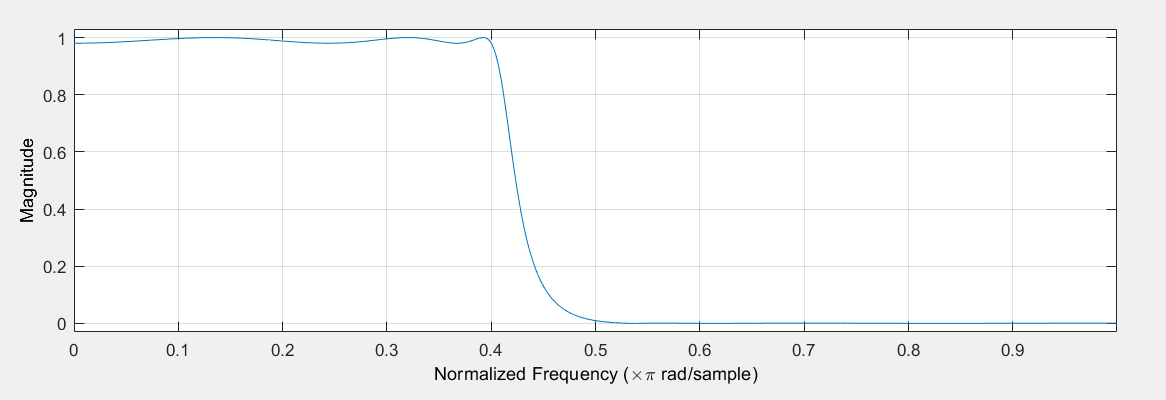

         **Magnitude in DB:-**

         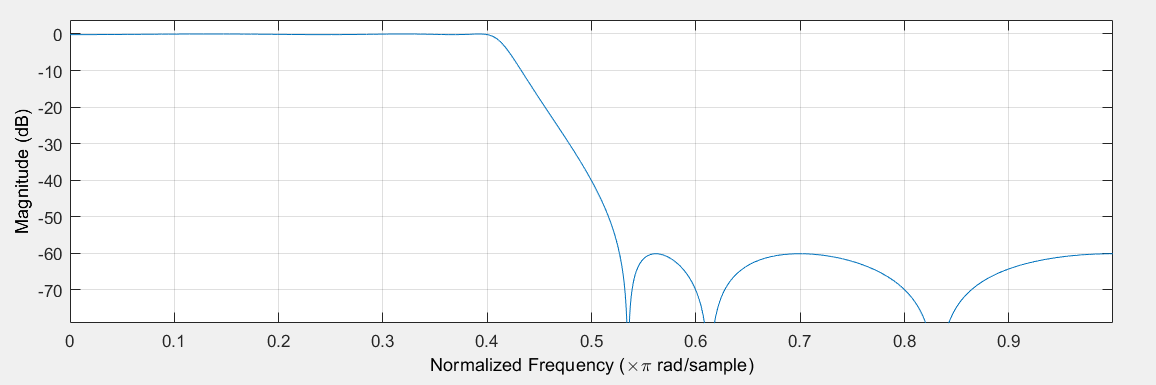                

        ***Group Delay*****:-**

        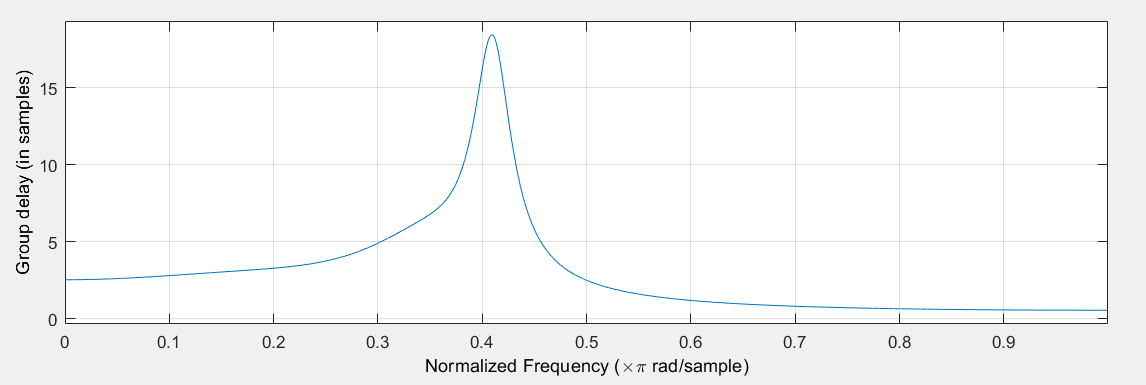

       **Pole Zero:-**

       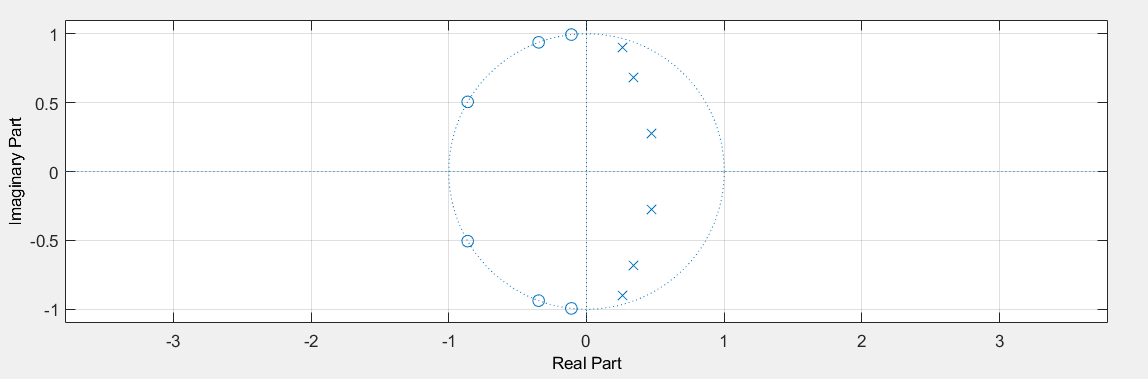

      **Observations:**

- The filter is stable as all the poles of the pole zero plot lie inside the unit circle.

- The group delay is highest in the transition band and below 15 in the passband. 

- Both passband and stopband show equiripple behaviour.

### FIR Window - Kaiser (10 Points)

% Enter the filter coefficients
%used the filterDesigner tool and exported the coefficients to the workspace

kaiserFilter = [-0.000248008102503338	0.000533374457591009	0.000955506925690995	-0.00154968707202433	-0.00235608304490556	0.00342065549295198	0.00479681083291731	-0.00654832668496626	-0.00875444824748636	0.0115187774745581	0.0149850623958054	-0.0193662614808247	-0.0250010530838665	0.0324725189942208	0.0428854227839861	-0.0586188547145853	-0.0858846674984382	0.147517760688666	0.449241499883213	0.449241499883213	0.147517760688666	-0.0858846674984382	-0.0586188547145853	0.0428854227839861	0.0324725189942208	-0.0250010530838665	-0.0193662614808247	0.0149850623958054	0.0115187774745581	-0.00875444824748636	-0.00654832668496626	0.00479681083291731	0.00342065549295198	-0.00235608304490556	-0.00154968707202433	0.000955506925690995	0.000533374457591009	-0.000248008102503338];

disp(kaiserFilter);

  Columns 1 through 12

   -0.0002    0.0005    0.0010   -0.0015   -0.0024    0.0034    0.0048   -0.0065   -0.0088    0.0115    0.0150   -0.0194

  Columns 13 through 24

   -0.0250    0.0325    0.0429   -0.0586   -0.0859    0.1475    0.4492    0.4492    0.1475   -0.0859   -0.0586    0.0429

  Columns 25 through 36

    0.0325   -0.0250   -0.0194    0.0150    0.0115   -0.0088   -0.0065    0.0048    0.0034   -0.0024   -0.0015    0.0010

  Columns 37 through 38

    0.0005   -0.0002



Answer the following:

- Order of the filter

*            Order of the filter is 37.*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            The Passband shows monotonic behaviour whereas the Stopband shows equiripple behaviour.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments.

          **Magnitude:-**

          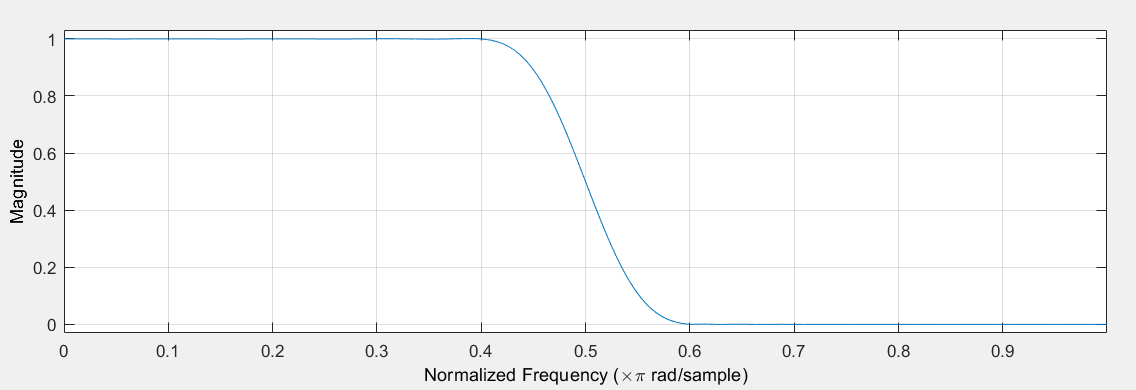

         **Magnitude in DB:-**

         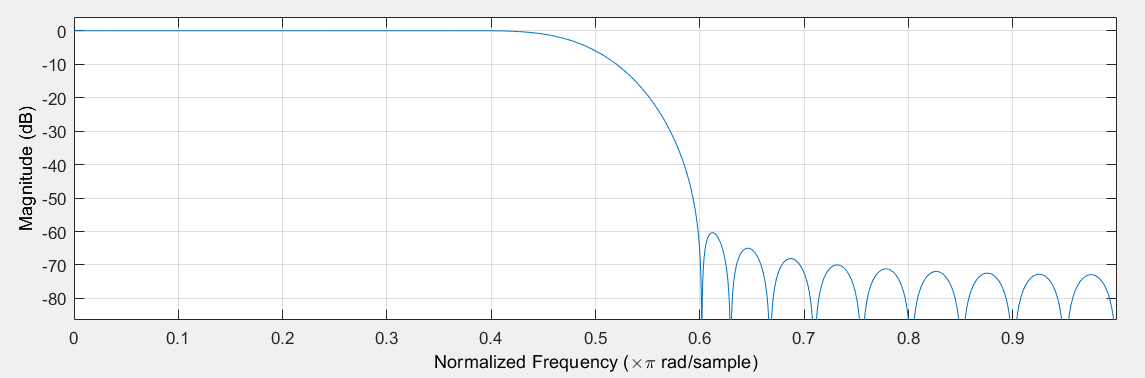                

        ***Group Delay*****:-**

        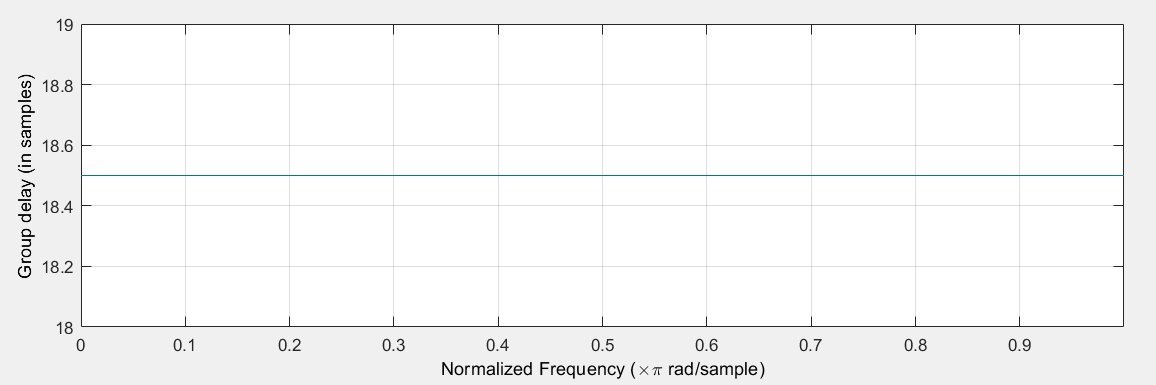

       **Pole Zero:-**

       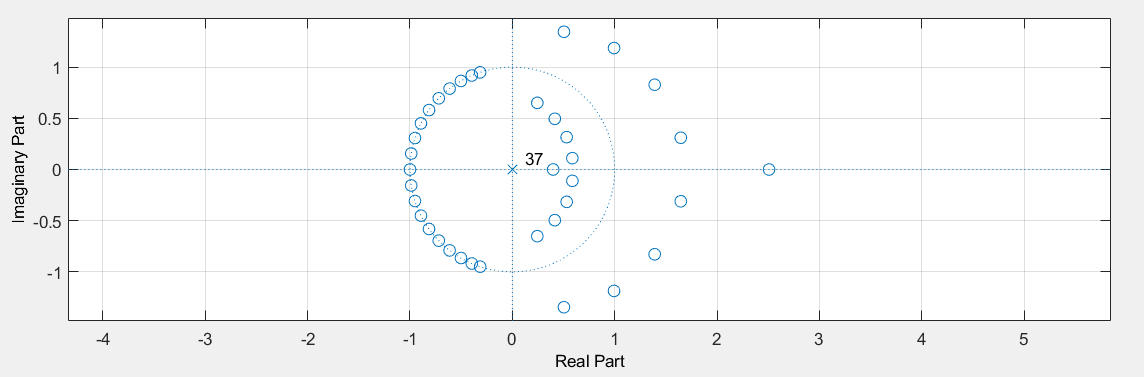

      **Observations:**

- The filter is stable as all the poles of the pole zero plot lie inside the unit circle.

- The group delay is constant.

- Stopband shows equiripple behaviour and passband shows monotonic behaviour.

### FIR Equiripple (10 Points)

% Enter the filter coefficients
%used the filterDesigner tool and exported the coefficients to the workspace

equirippleFilter = [-0.00255694603471546	-0.00759816315585803	-0.00150378550190926	0.0124251522917326	0.00549642501078310	-0.0221141921061701	-0.0138621891883555	0.0374390749425829	0.0308872916943620	-0.0659425442054115	-0.0738966529198243	0.157009809159164	0.438201641289614	0.438201641289614	0.157009809159164	-0.0738966529198243	-0.0659425442054115	0.0308872916943620	0.0374390749425829	-0.0138621891883555	-0.0221141921061701	0.00549642501078310	0.0124251522917326	-0.00150378550190926	-0.00759816315585803	-0.00255694603471546];

disp(equirippleFilter);

  Columns 1 through 12

   -0.0026   -0.0076   -0.0015    0.0124    0.0055   -0.0221   -0.0139    0.0374    0.0309   -0.0659   -0.0739    0.1570

  Columns 13 through 24

    0.4382    0.4382    0.1570   -0.0739   -0.0659    0.0309    0.0374   -0.0139   -0.0221    0.0055    0.0124   -0.0015

  Columns 25 through 26

   -0.0076   -0.0026



Answer the following:

- Order of the filter

*            Order of the filter is 25.*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            The Passband as well as the Stopband show equiripple behaviour.*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments.

          **Magnitude:-**

          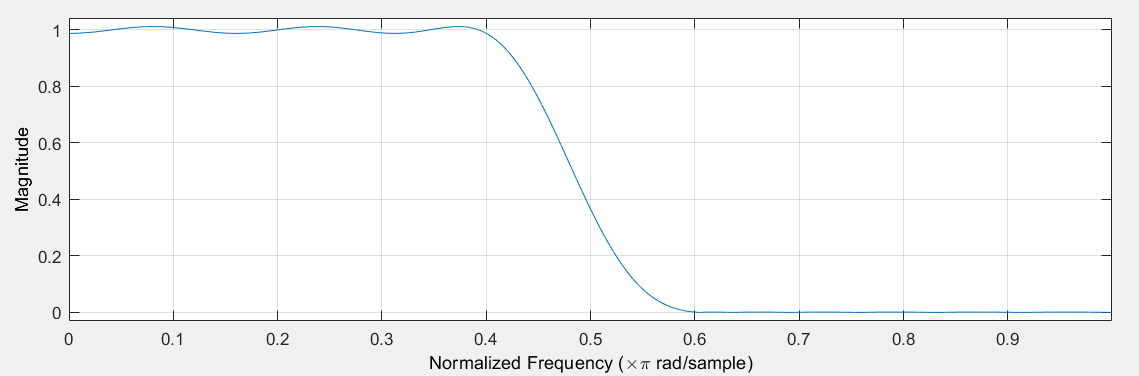

         **Magnitude in DB:-**

         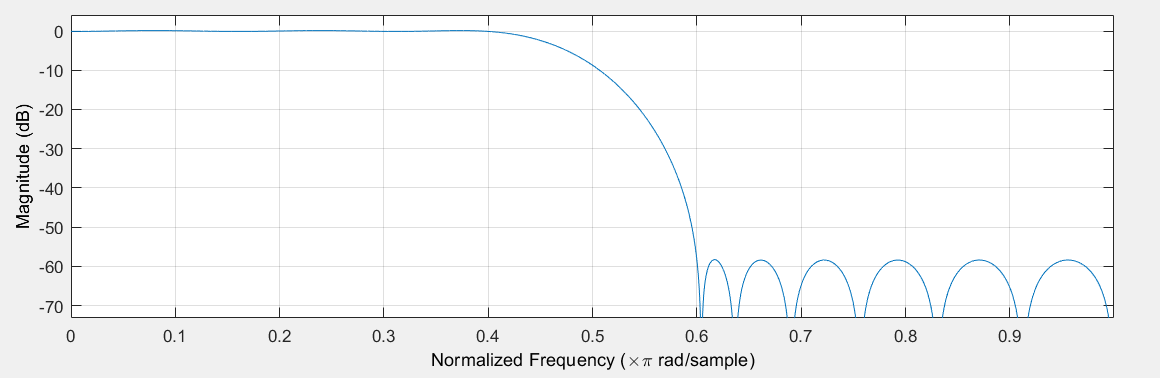                

        ***Group Delay*****:-**

        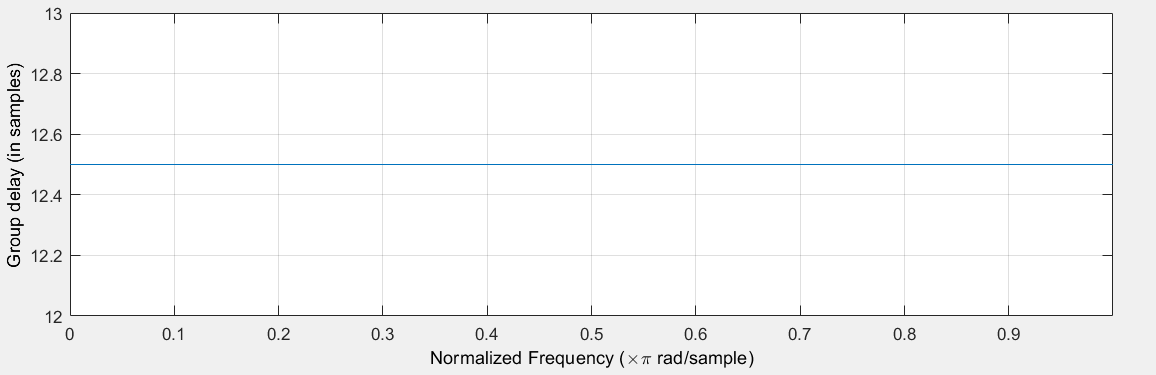

       **Pole Zero:-**

       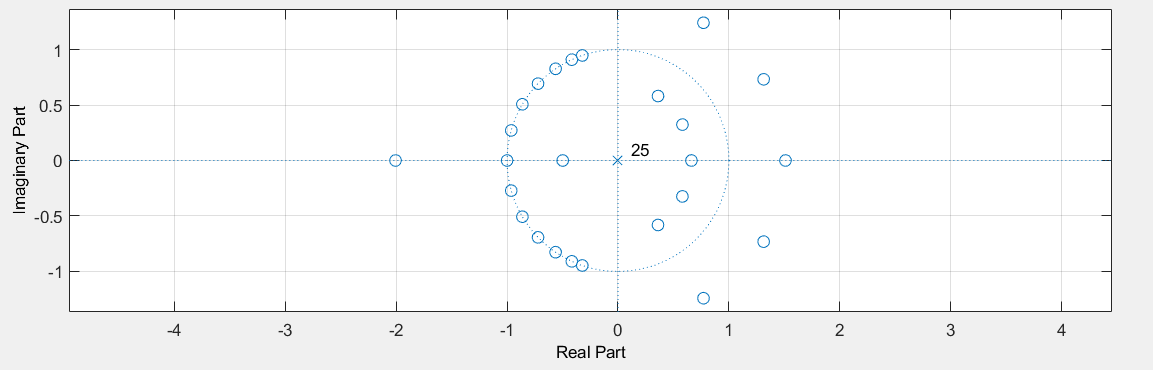

**      Observations:**

- The filter is stable as all the poles of the pole zero plot lie inside the unit circle.

- The group delay is constant.

- Both passband and stopband show equiripple behaviour.

### Common Questions (50 Points):

After all the filter designs are completed, answer the below questions. 

- Among IIR filters, which filter gives the lowest order? What is the practical use of having a lowest order filter (think in terms of number of multiplications in the implementation)? 

            Among IIR filters, we obtain the Lowest order of 6 for the **Elliptic IIR filter. **As we learned in analog circuits course the order of a butterworth filterdepends on its complexity the more is the order more will be the number of capacitors and inductors, we can generally say that as the order of the filter decreases the complexity of the filter also decreases here complexity can be refered to as the multiplications and operations required. 

- Among the FIR filters, which method gives the lowest order? Compare this with orders of IIR filters. 

            Among FIR filters, we obtain the Lowest order  of 25 for the **Equiripple FIR filter**. The order of this FIR filter is very high as compared to the orders of the IIR filters, this is because the IIR filters have lesser coefficients as compared to FIR filters as the IIR filters can be represented in Direct form I and II but FIR cannot.       (no feedback in FIR). 

- For a given filter specification, if you want the filter order to be as small as possible, which implemetation would you choose, FIR or IIR? Which one among them? 

            If we want the order of our filter to be small we will choose a **IIR filter** desgn.

- FIR filters are always stable, but IIR filters may or may not be stable (True or False)? 

            **True**, IIR filters are not always stable whereas FIR filters are always stable. IIR filters have a polynomial fraction form and if the denominator is zero then the filter becomes unstable.

- Comment on the group delays of FIR and IIR filters. Which design would you prefer (FIR or IIR) if the filter order is not important but a constant group delay is required? 

            If we want a filter with constant group delay we will choose a **FIR filter** design, as the IIR filters have variable group delay whereas FIR filters have constant group delays. 

## Minimum-Phase Filters (60 Points)

Consider the following scenario, where a message sequence $x[n]$is sent over a wireless channel and you receive, $y[n]$, via a multi-path channel (modeled as an LTI system, represented within the red box) with system function: 

$H(z) = \frac{z^{-1}-1/3}{1-0.9z^{-1}}$. 

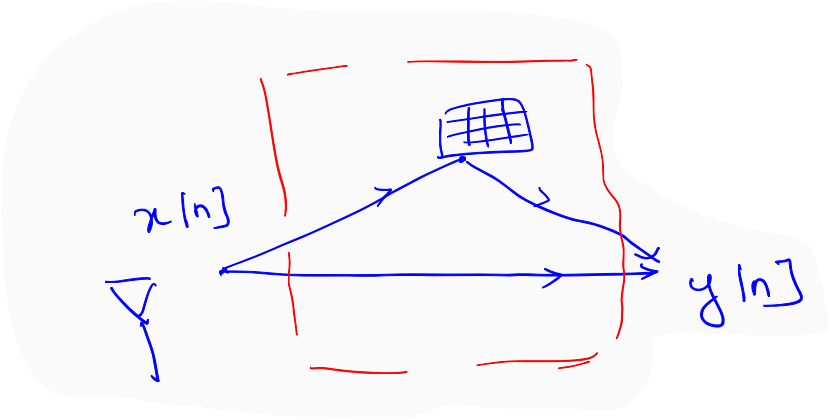

Suppose that the received sequence, $y[n]$ is 

y = repmat([1.0 0.5],1, 50); 

Now, recover $x[n]$ from this $y[n]$, i.e., get an estimate of $x[n], $ called as $\hat{x}[n]$, using a stable and causal filter. $x[n] $ and $\hat{x}[n]$must have the same amplitudes, but phases can be different.  

Hint: First do the minimum phase decomposition as follows: $H(z)  =  H_{\min}(z)H_{ap}(z)$ and pass $y[n]$ to the filter $1/H_{\min}(z)$ to get $\hat{x}[n]$. Refer to "Week-5 Video-3.mp4". See [https://spinlab.wpi.edu/courses/ece503_2014/7dot3.mp4](https://spinlab.wpi.edu/courses/ece503_2014/7dot3.mp4) for understanding why minimum phase systems are called as *minimum* phase systems. 

% WRITE YOUR CODE TO FIND AN ESTIMATE OF x[n], using minimum-phase -
% all-pass decomposition
zeros = [3];
poles = [0.9];
gain = 1/3;
Ts = 1; 

H_Z = zpk(zeros,poles,gain,Ts)%Transfer function of H(z)


H_Z =
 
  0.33333 (z-3)
  -------------
     (z-0.9)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



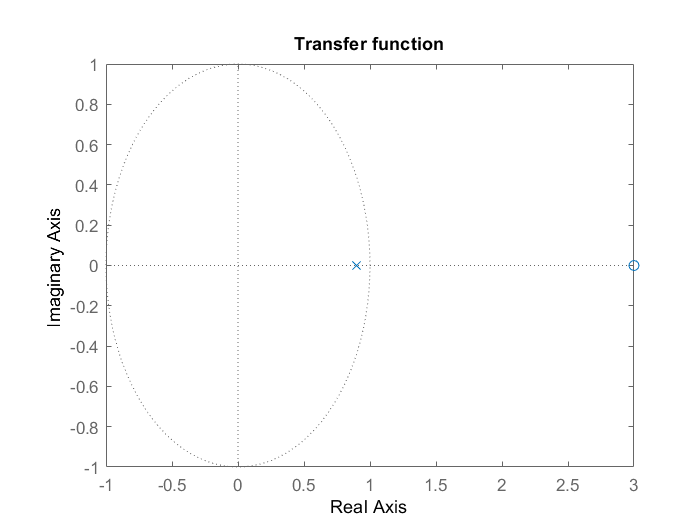

pzmap(H_Z);
title("Transfer function");

% adding one pole and zero at z = 1/3
zero1 = [3,1/3];
pole1 = [1/3,0.9];
H_Z_new = zpk(zero1,pole1,gain,Ts)%Transfer function of Hmin(z)


H_Z_new =
 
  0.33333 (z-3) (z-0.3333)
  ------------------------
     (z-0.3333) (z-0.9)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



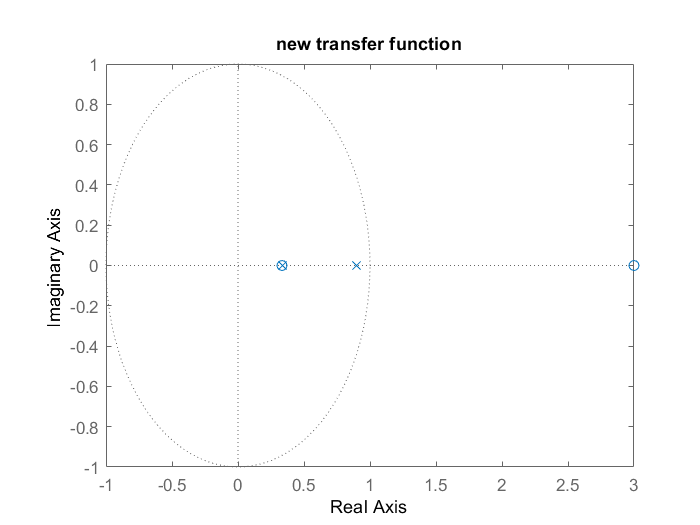

pzmap(H_Z_new);
title("new transfer function");

%separating the all pass filter
zeroap = [3];
poleap = [1/3];
H_Z_ap = zpk(zeroap,poleap,gain,Ts)


H_Z_ap =
 
  0.33333 (z-3)
  -------------
   (z-0.3333)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



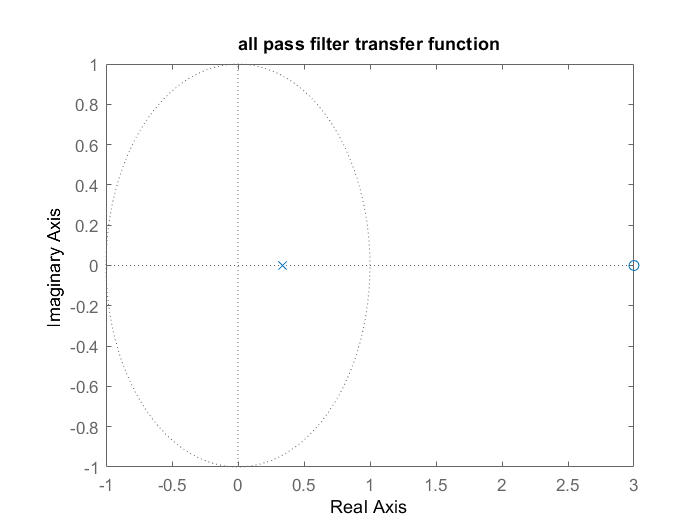

pzmap(H_Z_ap)
title("all pass filter transfer function")

%minimum phase transfer function 
zero_min = [1/3];
pole_min = [0.9];
H_Z_min = zpk(zero_min,pole_min,gain,Ts)


H_Z_min =
 
  0.33333 (z-0.3333)
  ------------------
       (z-0.9)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



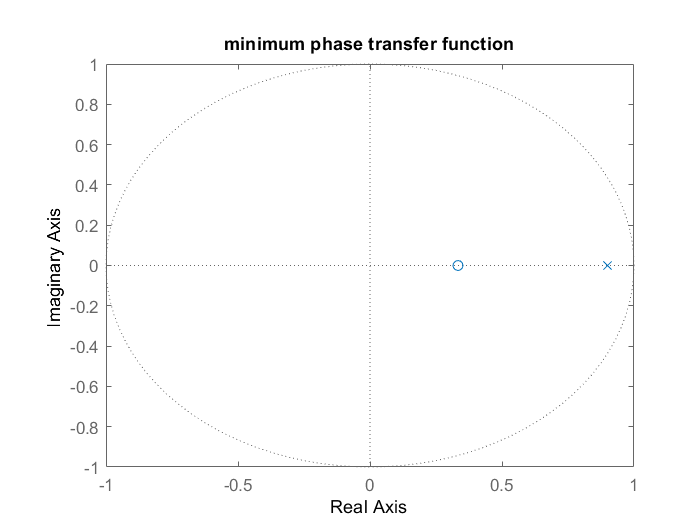

pzmap(H_Z_min);
title("minimum phase transfer function")

%Inverse transfer function
H_inv_min= 1/H_Z_min


H_inv_min =
 
  3 (z-0.9)
  ----------
  (z-0.3333)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



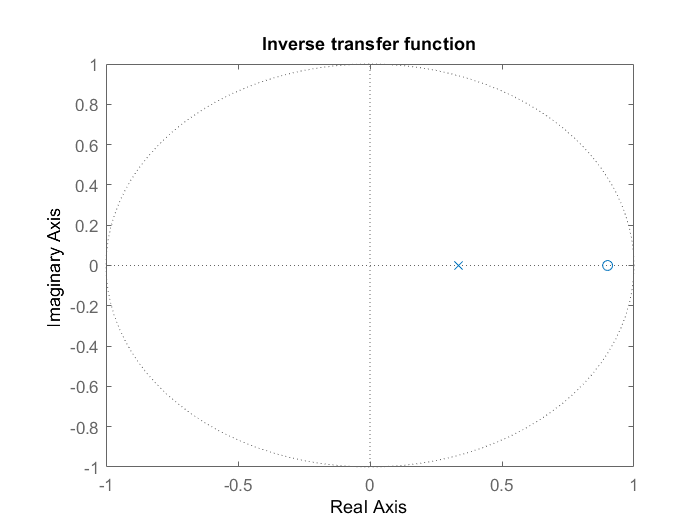

pzmap(H_inv_min);
title("Inverse transfer function");

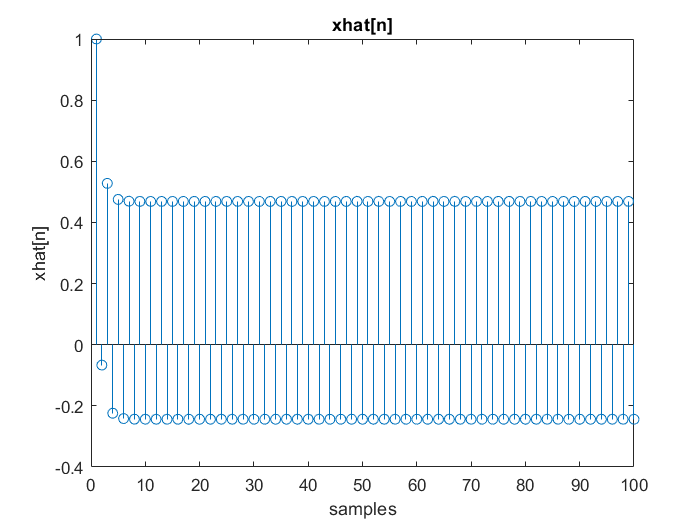

%computing the input x[n]
[num , den] = tfdata(H_inv_min/3);
num = cell2mat(num);
den = cell2mat(den);
xhat = filter(num , den , y);
stem(xhat);
title("xhat[n]");
xlabel("samples");
ylabel("xhat[n]");

- Comment on the pole-zero locations of the all-pass filters. Where are the poles and zeros of the all-pass filter, in the minimum-phase - all pass decomposition of the above channel system function ($H(z)  =  H_{\min}(z)H_{ap}(z)$)?  

            *The all pass filter has its pole at z = 1/3 and zero at z = 3, we can observe that the transfer function of the all pass filter is:*

             $H_{\textrm{ap}} \left(z\right)=\frac{\left(z^{-1} -3\;\right)}{3\left(1-\frac{z^{-1} }{3}\right)}$ and the corresponding frequency response will be $H_{\textrm{ap}} \left(e^{j\omega } \right)=\frac{1-\left(\frac{{\;e}^{j\omega } }{3}\right)}{1-\left(\frac{e^{-j\omega } }{3}\right)}$  and $\left|H_{\textrm{ap}} \left(e^{j\omega } \right)\right|=1$ 

            as the magnitude of the filter is constant for all frequencies we can say that $H_{\textrm{ap}} \left(e^{j\omega } \right)$ it is an all pass filter.

- Plot the magnitude and phase responses  of the $H_{ap}(z)$ obtained above. Comment on their behaviour. 

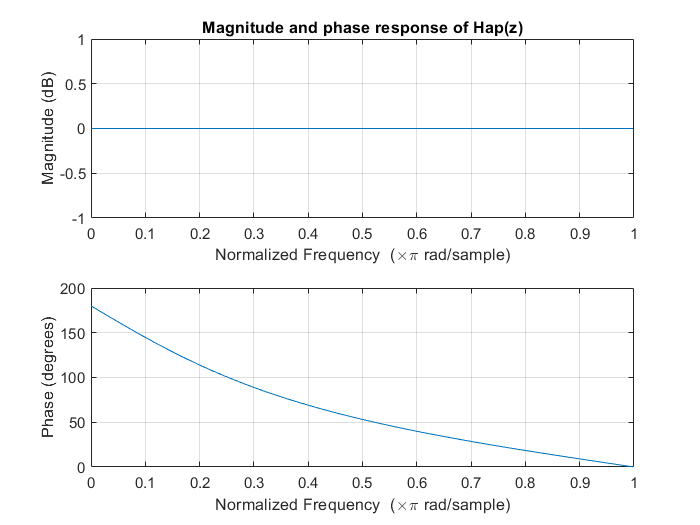

%frequency response of the all pass filter.
[num , den] = tfdata(H_Z_ap);
freqz(cell2mat(num),cell2mat(den))
title("Magnitude and phase response of Hap(z)");

As seen above theoretically we had guessed that the magnitude response will be constant for all frequencies, now by looking at the plots we can confirm that the magnitude response is indeed an all pass filter(constant for all frequencies).

As far as phase is concerned we can see that phase is not constant and hence there will be a delay introduced in the output. We won't recover exact sequence x[n] after taking the inverse of the transfer function, instead we will get a phase shifted version of x[n] i.e. $\hat{x}[n]$. 

There are other filter design methods as well, as you might have noted in the Filter Designer tool. However, we are not interested in them in this course. You now have sufficient knowledge on filter design and analysis. Hence, if required, you should be able to pick them up easily when required. 

### Thank you!